clearvars

% Init param
% Definim N i M
M_values = zeros(9, 1);
for i = 1:length(M_values)
    M_values(i) = 2^i;  
end
% M_values = [2^8, 2^9, 2^10];
N_values = zeros(20, 1);
for j = 1:length(N_values)
    N_values(j) = j;  
end

% Fem grid
[M_grid, N_grid] = meshgrid(M_values, N_values);

%% SNR + rho
SNR = 1.0;
current_rho = 0.5;

% Matriu per desar els temps d'execució
T_elapsed = zeros(length(N_values), length(M_values));  % Files: N, Columnes: M

%% Bucle doble 
for col = 1:length(M_values)
    % Generem simbols i probs per Mi
    [x, q] = PAM_generator(M_values(col));
    for row = 1:length(N_values)
        % Generem cuadratura i pesos per Ni
        [z, w] = GaussHermite_Locations_Weights(N_values(row));
        % Matrius
        [Q, pi_, G] = matrix_generator(N_values(row), q, x, w, z, SNR);
        
        tic;                                        % Time starts
        F0_val = F0_F0p(Q, pi_, G, current_rho);
        elapsed_time = toc;                         % Time ends

        
        % Desem temps en la matriu
        T_elapsed(row, col) = elapsed_time;
    end
end

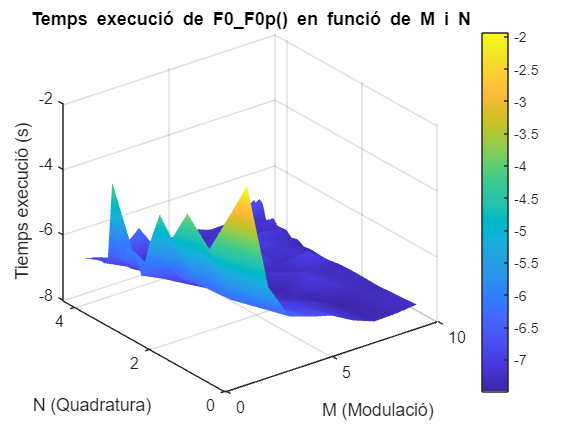

%% Grafic pla
figure;
% Grid 
T = T_elapsed ./ ((M_grid).^2.* N_grid.^2);
surf(log2(M_grid), log2(N_grid), log10(T));
shading interp; 
colormap(parula);
colorbar;
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
zlabel('Tiemps execució (s)');
title('Temps execució de F0\_F0p() en funció de M i N');
grid on;

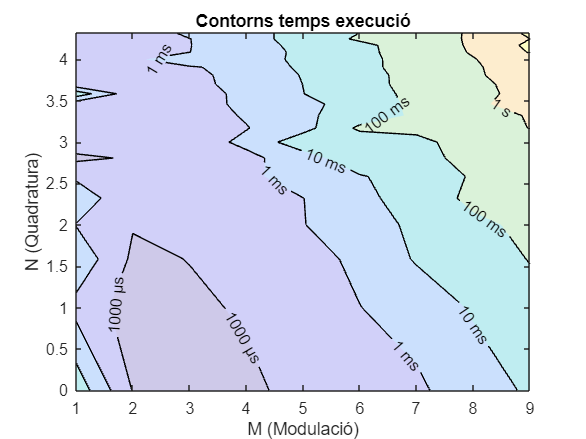

%% Graficar líneas de contorno
figure;
T = log10(T_elapsed);
contourf(log2(M_grid), log2(N_grid), T, -10:10, 'ShowText', true, ...
    'LabelFormat',@mylabelfun, ...
    'FaceAlpha',0.25);
xlabel('M (Modulació)');
ylabel('N (Quadratura)');
title('Contorns temps execució');

function labels = mylabelfun(vals)
    labels = string.empty;
    for i = 1:length(vals)
        switch vals(i)
            case 2
                labels(i) = '100 s';
            case 0
                labels(i) = '1 s';
            case 1
                labels(i) = '10 s';
            case 3
                labels(i) = '1000 s';
            case -1
                labels(i) = '100 ms';
            case -2
                labels(i) = '10 ms';
            case -3
                labels(i) = '1 ms';
            case -4
                labels(i) = '1000 μs';
            otherwise
                labels(i) = '??';      
        end
    end

end